Con este codigo se analizara todos los angulos. Creo que tronco no es igual a cadera bro por el momento le puse tronco al angulo de cadera chekea pes luis

clear;
files = dir('angulos_recortados\*.csv');

for k = 1:length(files)
    segmentoR = {};
    segmentoC = {};
    segmentoT = {};
    T = readtable("angulos_recortados\"+files(k).name);

    t = T.Time;
    % Angulo de cadera
    theta1 = calcAngles(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_a_0_X,...
        T.Angle1_a_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);
    % Angulo de rodilla
    theta2 = calcAngles(...
        T.Angle2_o_0_X,...
        T.Angle2_o_0_Y,...
        T.Angle2_a_0_X,...
        T.Angle2_a_0_Y,...
        T.Angle2_b_0_X,...
        T.Angle2_b_0_Y);
    
    % Angulo de tronco
    theta3 = calcAnglesT(...
        T.Angle1_o_0_X,...
        T.Angle1_o_0_Y,...
        T.Angle1_b_0_X,...
        T.Angle1_b_0_Y);


    % Correcion de angulo
    theta2 = 180 - theta2;
    theta3 = 180 - theta3;
    
    % Hallar puntos para segmentar
    [~,locs] = findpeaks(theta1,...
    'MinPeakDistance',50,...
    'MinPeakProminence',10);

    % Segmentación
    xC = theta1;
    xR = theta2;
    xT = theta3;
    cortes = [1, locs', length(theta1)];
    for i = 1:length(cortes)-1
        segmentoR{i} = xR(cortes(i):cortes(i+1));
        segmentoC{i} = xC(cortes(i):cortes(i+1));
        segmentoT{i} = xT(cortes(i):cortes(i+1));

        segmentoTiempo{i} = t(cortes(i):cortes(i+1));
    end

    % Guardado de de data
    data(k).archivo = files(k).name;
    data(k).t = t;
    data(k).cadera = theta1;
    data(k).rodilla = theta2;
    data(k).tronco = theta3;
    data(k).segmentosR = segmentoR;
    data(k).segmentosC = segmentoC;
    data(k).segmentosT = segmentoT;
    data(k).segmentosTiempo = segmentoTiempo;
    
    for r = 1:length(data(k).segmentosR)

        thetaR = data(k).segmentosR{r};
    
        [~,locsR] = max(thetaR);
    
        thetaC = data(k).segmentosC{r};
    
        [~,locsC] = min(thetaC);
        
        thetaT = data(k).segmentosT{r};
        [~,locsT] = min(thetaT);
    
        data(k).locsR{r} = locsR;
        data(k).locsC{r} = locsC;
        data(k).locsT{r} = locsT;

        % Verificacion visual
        % figure(Position=[0,0,1200,300])
        % subplot(131)
        % plot(thetaR)
        % hold on
        % plot(locsR, thetaR(locsR), 'ro', 'MarkerFaceColor','r');grid on
        % subplot(132)
        % plot(thetaC)
        % hold on
        % plot(locsC, thetaC(locsC), 'ro', 'MarkerFaceColor','r');
        % subplot(133)
        % plot(thetaT)
        % hold on
        % plot(locsT, thetaT(locsT), 'ro', 'MarkerFaceColor','r');grid on
    
    end

    % Verificacion visual
    %figure;
    %plot(t,theta1); hold on; plot(t(locs),theta1(locs),'ro'); grid on
end

% Separar datos entre pacientes
Participante(1).nombre = "P1";
Participante(1).series = data(1:5);

Participante(2).nombre = "P2";
Participante(2).series = data(6:10);

for p = 1:length(Participante)

    totalRepsT = 0;
    totalRepsR = 0;
    fprintf("Participante %d\n",p)
    for r = 1:length(Participante(p).series)

        thetaR = Participante(p).series(r).rodilla;
        [~,locsR] = findpeaks(thetaR,...
            'MinPeakProminence',8,...
            'MinPeakDistance',100);

        thetaC = Participante(p).series(r).tronco;
        [~,locsT] = findpeaks(-thetaC,...
            'MinPeakProminence',20,...
            'MinPeakDistance',100);

        totalRepsT = totalRepsT + length(locsT);
        totalRepsR = totalRepsR + length(locsR);

        % figure(Position=[0,0,1200,300])
        % subplot(121)
        % plot(thetaR)
        % hold on
        % plot(locsR, thetaR(locsR), 'ro', 'MarkerFaceColor','r');grid on
        % subplot(122)
        % plot(thetaT)
        % hold on
        % plot(locsT, thetaT(locsT), 'ro', 'MarkerFaceColor','r');grid on
        fprintf("Repeticiones serie %d: %d\n",r,length(locsT));
    end
    fprintf("Participante %d\n",p)
    fprintf('Total de repeticiones de tronco: %d\n',totalRepsT)
    fprintf('Total de repeticiones de rodilla: %d\n',totalRepsR)
    fprintf("Total: %d\n",(totalRepsR+totalRepsT)/2)

end

Participante 1


Repeticiones serie 1: 1
Repeticiones serie 2: 3
Repeticiones serie 3: 3
Repeticiones serie 4: 6
Repeticiones serie 5: 4


Participante 1


Total de repeticiones de tronco: 17


Total de repeticiones de rodilla: 17


Total: 17


Participante 2


Repeticiones serie 1: 4
Repeticiones serie 2: 4
Repeticiones serie 3: 2
Repeticiones serie 4: 4
Repeticiones serie 5: 4


Participante 2


Total de repeticiones de tronco: 18


Total de repeticiones de rodilla: 18


Total: 18


Participante(1).seriesAnalizar = [2,3,5];
Participante(2).seriesAnalizar = [2,4,5];
for p = 1:length(Participante)

    seriesAnalizar = Participante(p).seriesAnalizar;

    for s = seriesAnalizar

        serie = Participante(p).series(s);

        for r = 1:length(serie.segmentosC)

            rep = struct();

            thetaC = serie.segmentosC{r};
            thetaR = serie.segmentosR{r};
            thetaT = serie.segmentosT{r};

            tRep = serie.segmentosTiempo{r};

            idxPI  = 1;
            idxPMF = serie.locsC{r};
            idxPF  = length(thetaC);

            rep.numRep = r;

            rep.thetaC_PI  = thetaC(idxPI);
            rep.thetaC_PMF = thetaC(idxPMF);
            rep.thetaC_PF  = thetaC(idxPF);

            % idxPMF = serie.locsR{r};
            rep.thetaR_PI  = thetaR(idxPI);
            rep.thetaR_PMF = thetaR(idxPMF);
            rep.thetaR_PF  = thetaR(idxPF);

            % idxPMF = serie.locsT{r};
            rep.thetaT_PI  = thetaT(idxPI);
            rep.thetaT_PMF = thetaT(idxPMF);
            rep.thetaT_PF  = thetaT(idxPF);

            rep.ROM_C = calcROM(thetaC);
            rep.ROM_R = calcROM(thetaR);
            rep.ROM_T = calcROM(thetaT);

            [rep.texc, rep.tcon] = calcPhases(tRep,idxPMF);
            rep.ttot = calcDuration(tRep);

            Participante(p).series(s).rep(r) = rep;

        end
    end
end

% Estadistica
campos = {...
    'thetaC_PI','thetaC_PMF','thetaC_PF',...
    'thetaR_PI','thetaR_PMF','thetaR_PF',...
    'thetaT_PI','thetaT_PMF','thetaT_PF',...
    'ROM_C','ROM_R','ROM_T',...
    'texc','tcon','ttot'};

for p = 1:length(Participante)

    for c = 1:length(campos)

        campo = campos{c};
        valores = [];

        for s = Participante(p).seriesAnalizar

            serie = Participante(p).series(s);

            for r = 1:length(serie.rep)

                valores(end+1) = serie.rep(r).(campo);

            end
        end

        Participante(p).stats.(campo) = calcStats(valores);

    end

end

campos = fieldnames(Participante(1).stats);

for c = 1:length(campos)

    campo = campos{c};

    Resultados.tabla(c).Variable = campo;

    Resultados.tabla(c).P1_mean = ...
        Participante(1).stats.(campo).mean;

    Resultados.tabla(c).P1_std = ...
        Participante(1).stats.(campo).std;

    Resultados.tabla(c).P2_mean = ...
        Participante(2).stats.(campo).mean;

    Resultados.tabla(c).P2_std = ...
        Participante(2).stats.(campo).std;

    Resultados.tabla(c).DiffAbs = abs( ...
        Participante(1).stats.(campo).mean - ...
        Participante(2).stats.(campo).mean );

end
struct2table(Resultados.tabla)

ans = 15×6 table
       Variable       P1_mean    P1_std     P2_mean    P2_std      DiffAbs 
    ______________    _______    _______    _______    _______    _________

    {'thetaC_PI' }    173.08      2.9422    179.15      3.6088       6.0638
    {'thetaC_PMF'}    38.264      6.1832    63.686      3.8148       25.423
    {'thetaC_PF' }    171.83      3.1191    180.54      3.4901       8.7067
    {'thetaR_PI' }    15.325      2.4858    9.3976       2.577       5.9272
    {'thetaR_PMF'}    30.708      5.9788    26.375      3.6674       4.3336
    {'thetaR_PF' }    15.104      2.7201    8.5806       2.524       6.5235
    {'thetaT_PI' }    179.02      1.6202    182.36      3.0208       3.3328
    {'thetaT_PMF'}    66.591       4.639    90.888      2.8211       24.296
    {'thetaT_PF' }

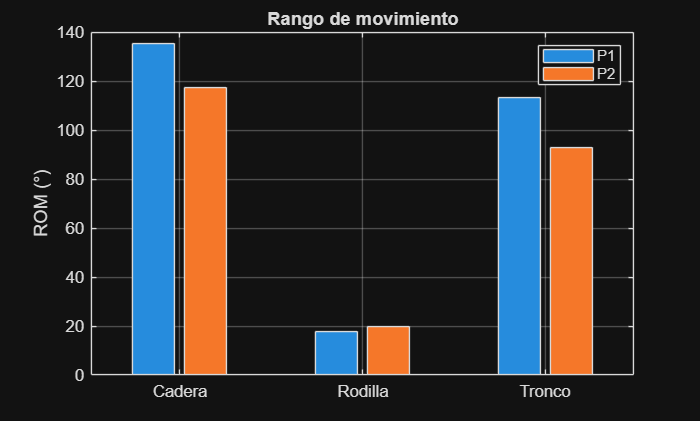

% Graficos estadisticos
% Figura 1: ROM (P1 vs P2)
variables = {'ROM_C','ROM_R','ROM_T'};

P1 = zeros(1,length(variables));
P2 = zeros(1,length(variables));

for i = 1:length(variables)

    P1(i) = Participante(1).stats.(variables{i}).mean;
    P2(i) = Participante(2).stats.(variables{i}).mean;

end

figure
bar([P1;P2]')
grid on

set(gca,'XTickLabel',{'Cadera','Rodilla','Tronco'})

ylabel('ROM (°)')
legend('P1','P2')
title('Rango de movimiento')

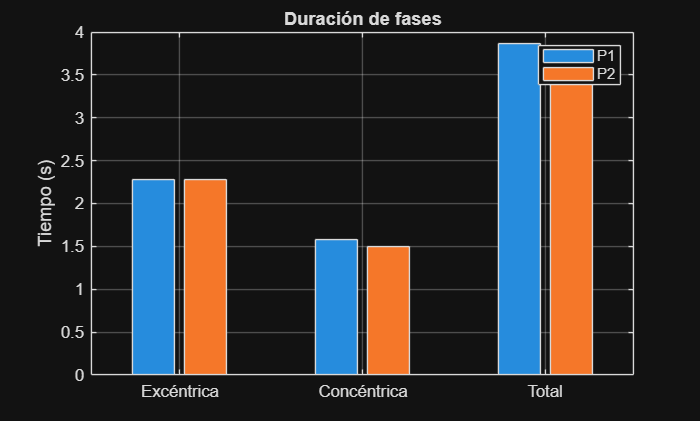



% Figura 2: Duración de fases
variables = {'texc','tcon','ttot'};

P1 = zeros(1,length(variables));
P2 = zeros(1,length(variables));

for i = 1:length(variables)

    P1(i) = Participante(1).stats.(variables{i}).mean;
    P2(i) = Participante(2).stats.(variables{i}).mean;

end

figure
bar([P1;P2]')
grid on

set(gca,'XTickLabel',...
    {'Excéntrica','Concéntrica','Total'})

ylabel('Tiempo (s)')
legend('P1','P2')
title('Duración de fases')

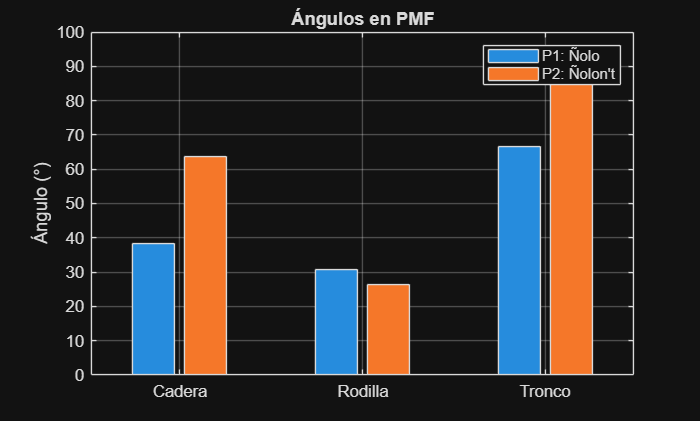


% Figura 3: Ángulos en PMF
variables = {'thetaC_PMF','thetaR_PMF','thetaT_PMF'};

P1 = zeros(1,length(variables));
P2 = zeros(1,length(variables));

for i = 1:length(variables)

    P1(i) = Participante(1).stats.(variables{i}).mean;
    P2(i) = Participante(2).stats.(variables{i}).mean;

end

figure
bar([P1;P2]')
grid on

set(gca,'XTickLabel',...
    {'Cadera','Rodilla','Tronco'})

ylabel('Ángulo (°)')
legend('P1: Ñolo',"P2: Ñolon't")
title('Ángulos en PMF')

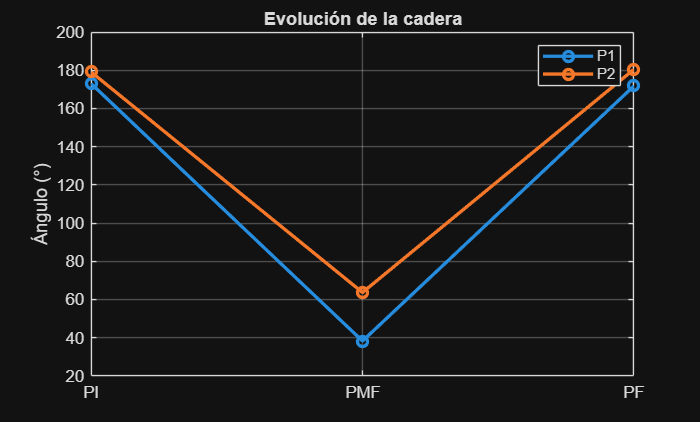


% Figura 4: PI → PMF → PF

P1 = [ ...
    Participante(1).stats.thetaC_PI.mean,...
    Participante(1).stats.thetaC_PMF.mean,...
    Participante(1).stats.thetaC_PF.mean];

P2 = [ ...
    Participante(2).stats.thetaC_PI.mean,...
    Participante(2).stats.thetaC_PMF.mean,...
    Participante(2).stats.thetaC_PF.mean];

figure
plot(P1,'o-','LineWidth',2)
hold on
plot(P2,'o-','LineWidth',2)

set(gca,'XTick',1:3)
set(gca,'XTickLabel',{'PI','PMF','PF'})

ylabel('Ángulo (°)')
legend('P1','P2')
grid on

title('Evolución de la cadera')

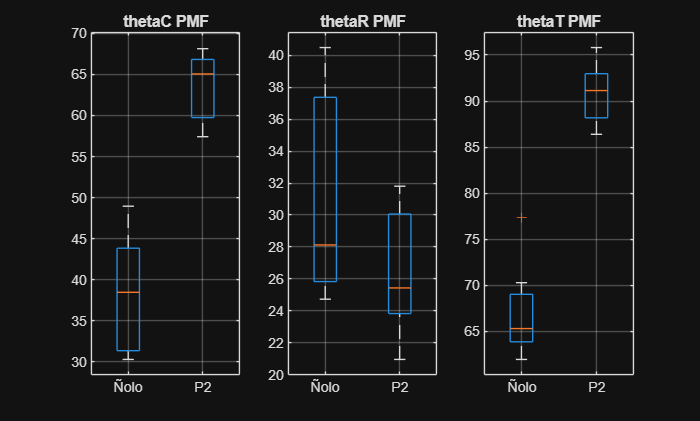

%
x = [ ...
    Participante(1).stats.ROM_C.data ...
    Participante(2).stats.ROM_C.data ];

grupo = [ ...
    ones(1,length(Participante(1).stats.ROM_C.data)) ...
    2*ones(1,length(Participante(2).stats.ROM_C.data)) ];

variables = {'thetaC_PMF','thetaR_PMF','thetaT_PMF'};

figure

for i = 1:3

    subplot(1,3,i)

    P1 = Participante(1).stats.(variables{i}).data;
    P2 = Participante(2).stats.(variables{i}).data;

    x = [P1 P2];

    g = [ ...
        ones(1,length(P1)) ...
        2*ones(1,length(P2)) ];

    boxplot(x,g,'Labels',{'Ñolo','P2'})

    title(strrep(variables{i},'_',' '))
    grid on

end














% Funciones
function theta = calcAngles(Ox, Oy, Ax, Ay, Bx, By)

    OAx = Ax - Ox;
    OAy = Ay - Oy;

    OBx = Bx - Ox;
    OBy = By - Oy;

    dotprod = OAx.*OBx + OAy.*OBy;
    crossprod = OAx.*OBy - OAy.*OBx;

    theta = atan2d(crossprod, dotprod);

    theta(theta < 0) = theta(theta < 0) + 360;

end
function theta = calcAnglesT(Ox, Oy, Ax, Ay)

    OAx = Ax - Ox;
    OAy = Ay - Oy;
    
    theta = atan2d(OAx, OAy);
end
% Funciones para calcular variables individuales
function rom = calcROM(theta)

    rom = max(theta) - min(theta);

end
function dur = calcDuration(t)

    dur = t(end) - t(1);

end
% idxMax son los locs de rodilla o tronco
function [tEcc,tCon] = calcPhases(t,idxMax) 

    tEcc = t(idxMax) - t(1);

    tCon = t(end) - t(idxMax);

end

% Funciones para analizar estadistica
function S = calcStats(x)

    S.data = x;
    S.mean = mean(x);
    S.std  = std(x);
    S.min  = min(x);
    S.max  = max(x);
    S.rng  = max(x) - min(x);

end
